clear all;

- Genere una señal senoidal portadora de 20Hz y una señal de información cosenoidal moduladora de 2 Hz. 

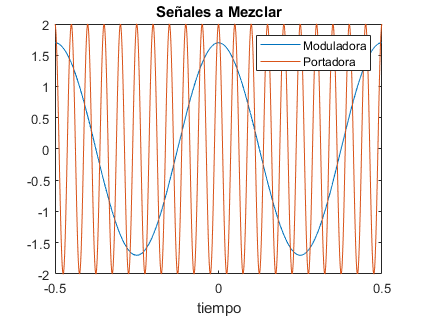

%Parametros
kps_64      =        64000;            %Muestreo
time        =        -.5:1/kps_64:.5;  %Tiempo de Muestreo
range_freq  =   -kps_64/2:1:kps_64/2;  %Frecuencia muestreada  
%señal Portadora
ap          =     2;
freq_port   =    20;            %Frecuencia de Portadora
wp          = 2*pi*freq_port;
port_sig    =  ap*cos(wp*time);
%señal moduladora
am          =    1.7;
freq_mod    =     2;            %Frecuencia de Moduladora
wm          =   2*pi*freq_mod;
mod_sig     =   am*cos(wm*time);
% Señales en tiempo
figure(1);
plot(time, mod_sig)
hold on
plot(time, port_sig)
title('Señales a Mezclar');
xlabel('tiempo')
legend({'Moduladora','Portadora'},'Location','northeast')
hold off

## Modulacion AM Convencional 

El indice de modulacion $\beta$ esta dado por la siguiente relacion


$$\beta =\frac{A_m }{A_p }$$


donde **Am** es la amplitud de la señal moduladora y **Ap** es la amplitud de la señal portadora.

index_mod   =       am/ap;

index_mod = 0.8500

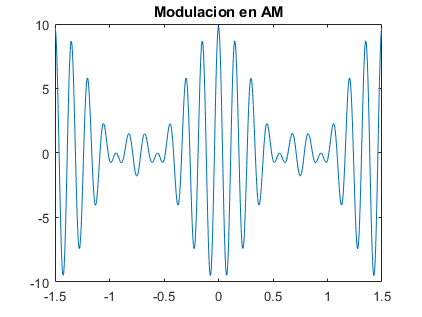

am_sig      =       am*mod_sig.*port_sig + ap*port_sig;
figure(2);
plot(time*3, am_sig);
title('Modulacion en AM');

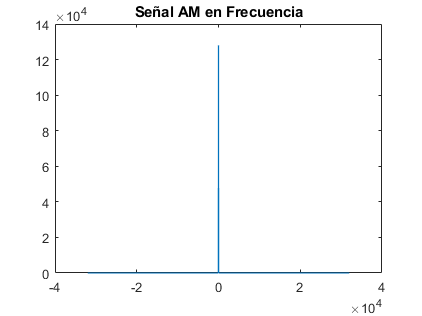

figure(3);
plot(range_freq,abs(ttof(am_sig)));
title('Señal AM en Frecuencia');

## Modulacion AM Doble Banda Lateral con Portadora Suprimida (DBLPS)

## Modulacion BLU